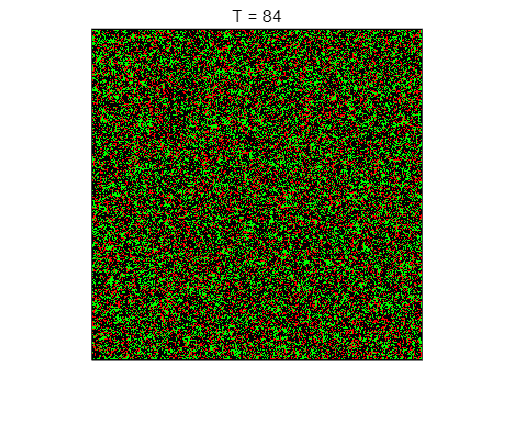

close all;
clc;
clear;%清屏命令
figure;%利用当前属性创建窗格
p=0.3;% 概率p，用来表示树生长的速度
f=6e-5;% 概率f,用来表示闪电击中的概率
axes;%建立坐标轴
rand('state',0);
%这个命令应该是回到最开始的种子，
%否则森林的状态在你第二次运行的时候是接着上一次运行的结果
%不是一个新的状态
set(gcf,'DoubleBuffer','on');
%设置的目的是为了防止在不断循环画动画的时候会产生闪烁的现象
S=round(rand(300)*2);
%将 X 的每个元素四舍五入为最近的整数,本质上就是一个四舍五入的函数
%初始化森林
Sk=zeros(302);%初始化Sk矩阵
Sk(2:301,2:301)=S;%%加边开始的森林初值，森林的边界为一列或者一行
%将其森林的部分插入这个矩阵中
% 红色表示正在燃烧(S中等于2的位置)% 绿色表示绿树(S中等于1的位置)% 黑色表示空格位(S中等于0的位置)
C=zeros(302,302,3);%构造一个302*302*3的张量（数组）
R=zeros(300);%初始化R矩阵
G=zeros(300);%初始化G矩阵
R(S==2)=1;%构成的向量的一个位置上对应的数为2，则给R赋值1
G(S==1)=1;%构成的向量的一个位置上对应的数为1，则给R赋值1

C(2:301,2:301,1)=R;%将C的第一层赋值为R矩阵
C(2:301,2:301,2)=G;%将C的第二层赋值为G矩阵

Ci=imshow(C);%在图窗中显示灰度图像 I
ti=0;%初始化时间
tp=title(['T = ',num2str(ti)]);%在标题处显示时间
while 1
    ti=ti+1;%时间的递增
    St=Sk;%St表示t时刻的森林情况，Sk矩阵代表着随机出来的森林情况
    St(Sk==2)=0;%正在燃烧的树变成空格位，经过一个时间间隔后
    Su=zeros(302);%初始化Su矩阵
    Sf=Sk;%Sf初始化为Sk
    Sf(Sf<1.5)=0;%将森林中的空白点和有树的点去掉，只留下着火点
    Sf=Sf/2;%着火点变为1，此处Sf只有着火和空格两种
    Su(2:301,2:301)=Sf(1:300,1:300)+Sf(1:300,2:301)+Sf(1:300,3:302) +...
        Sf(2:301,1:300)+Sf(2:301,3:302)+Sf(3:302,1:300) + ...
        Sf(3:302,2:301)+Sf(3:302,3:302);
    %对于矩阵中的一个点来说，周围八个点只要有一个点大于0，那么这个点就要变成着火状态（Sf=2）
    %所以这个命令是将矩阵中的一个点的周围八个点的数相加，这个数值就是周围八个点着火点的个数
    St((Su>0.5)&(Sk==1))=2;%如果绿树格位的最近邻居中有一个树在燃烧，则它变成正在燃烧的树；
    
    Se=Sk(2:301,2:301);%将Se初始化为最初森林
    Se(Se<0.5)=4;%% 空白地方赋值为4
    Se(Se<3)=0;%%有树和着火赋值为0
    Se(Se>3)=1;%%空白地方赋值为1
    %三步操作一起将空白处变为1，不是空白处变为0
    St(2:301,2:301)=St(2:301,2:301)+Se.*(rand(300)<p);
    %rand(300)<p是一个判断矩阵，对于rand(300)这个矩阵的每一项，如果小于p那么输出1，反之输出0
    %也就是在小于p时长树，大于p时不长树
    %更新t时刻的森林St     
    Ss=zeros(302);%初始化Ss矩阵
    Ss(Sk==1)=1;%%讨论绿树情况
    Ss(2:301,2:301)=Ss(1:300,1:300)+Ss(1:300,2:301)+Ss(1:300,3:302) +...
        Ss(2:301,1:300)+Ss(2:301,3:302)+Ss(3:302,1:300) + ...
        Ss(3:302,2:301)+Ss(3:302,3:302);
    %记录矩阵中的一个点的周围八个点一共有多少棵树
    %这个式子求出的值就是一个点周围树的个数
    Ss(Ss<7.5)=0;
    Ss(Ss>7.5)=1;
    %周围的树等于8棵时，Ss赋值为1
    %周围的树小于8棵时，Ss赋值为0
    d=find(Ss==1 & Sk==1);%查找非零元素的索引和值
    %返回一个包含数组 X 中每个非零元素的线性索引的向量。
    for k=1:length(d)
        r=rand(1);
        St(d(k))=round(2*(r<=f)+(r>f));
    end
    %在最近的邻居中没有正在燃烧的树的情况下树在每一时步以概率f(闪电)变为正在燃烧的树
    Sk=St;%更新t时刻的森林St
    R=zeros(302);%初始化R矩阵
    G=zeros(302);%初始化G矩阵
    R(Sk==2)=1;%当Sk中标记为2的点，也是表示着火点则在R中标记出来
    G(Sk==1)=1;%当Sk中标记为1的点，也是表示树的点在G中标记出来
  
    C(:,:,1)=R;%把C的第一层赋值为R
    C(:,:,2)=G;%把C的第二层赋值为G
  
    set(Ci,'CData',C);%第一行是显示图像，C是图像的矩阵，Ci上面有定义，是显示图像。
    set(tp,'string',['T = ',num2str(ti)]);%第二行是设置图像的标题，显示T=当前时刻
    pause(1);
end

close all;
clc;
clear;%清屏命令
figure;%利用当前属性创建窗格
p=0.01;% 概率p，用来表示树生长的速度
f=6e-5;% 概率f,用来表示闪电击中的概率
w=0.8;
axes;%建立坐标轴
rand('state',0);
%这个命令应该是回到最开始的种子，
%否则森林的状态在你第二次运行的时候是接着上一次运行的结果
%不是一个新的状态
set(gcf,'DoubleBuffer','on');
%设置的目的是为了防止在不断循环画动画的时候会产生闪烁的现象
% S=round((rand(300)/2+0.5)*2);
S=ones(300);
S(151,151)=2;
%将 X 的每个元素四舍五入为最近的整数,本质上就是一个四舍五入的函数
Sk=zeros(302);%初始化Sk矩阵
Sk(2:301,2:301)=S;%%加边开始的森林初值，森林的边界为一列或者一行
%将其森林的部分插入这个矩阵中
% 红色表示正在燃烧(S中等于2的位置)
% 绿色表示绿树(S中等于1的位置)
% 黑色表示空格位(S中等于0的位置)
C=zeros(302,302,3);%构造一个302*302*3的张量（数组）
R=zeros(300); %初始化R矩阵
G=zeros(300); %初始化G矩阵
R(S==2)=1;%构成的向量的一个位置上对应的数为2，则给R赋值1
G(S==1)=1;%构成的向量的一个位置上对应的数为1，则给R赋值1
C(2:301,2:301,1)=R;%将C的第一层赋值为R矩阵
C(2:301,2:301,2)=G;%将C的第二层赋值为G矩阵
Ci=imshow(C);%在图窗中显示灰度图像 I
ti=0;%初始化时间
tp=title(['T = ',num2str(ti)]);%在标题处显示时间
while 1 
    ti=ti+1;%时间的递增
    St=Sk;%St表示t时刻的森林情况，Sk矩阵代表着随机出来的森林情况
    St(Sk==2)=0;%正在燃烧的树变成空格位，经过一个时间间隔后
    Su=zeros(302);%初始化Su矩阵
    Sf=Sk;%Sf初始化为Sk
    Sf(Sf<1.5)=0;%将森林中的空白点和有树的点去掉，只留下着火点
    Sf=Sf/2; %着火点变为1，此处Sf只有着火和空格两种
    Su(2:301,2:301)=Sf(1:300,1:300)+Sf(1:300,2:301)+Sf(1:300,3:302) +...
        Sf(2:301,1:300)+Sf(2:301,3:302)+Sf(3:302,1:300) + ...
        Sf(3:302,2:301)+Sf(3:302,3:302);%对于矩阵中的一个点来说，周围八个点只要有一个点大于0，那么这个点就要变成着火状态（Sf=2）
    %所以这个命令是将矩阵中的一个点的周围八个点的数相加，这个数值就是周围八个点着火点的个数  
    St(Su>0.5&Sk==1)=2;%如果绿树格位的最近邻居中有一个树在燃烧，则它变成正在燃烧的树；
    %%对于着火点的更新（仅考虑规则1）
    for i=2:301
     for j=2:301
         r0=rand(1);
         if St(i,j)==2&&St(i-1,j)==1
             St(i-1,j)=round(2*(r0<=w)+(r0>w));
             St(i-2,j)=round(2*(r0<=w)+(r0>w));
         end
     end
 end
 
             
    %着火点的左侧的格子如果是树的话有w的概率变成着火的格子
    %%考虑风的因素的影响，着火点左侧有树的地方有可能着火
    
    Se=Sk(2:301,2:301);%将Se初始化为最初森林
    Se(Se<0.5)=4;%% 空白地方赋值为4
    Se(Se<3)=0;%%有树和着火赋值为0
    Se(Se>3)=1;%%空白地方赋值为1
    %三步操作一起将空白处变为1，不是空白处变为0
    St(2:301,2:301)=St(2:301,2:301)+Se.*(rand(300)<p);
    %rand(300)<p是一个判断矩阵，对于rand(300)这个矩阵的每一项，如果小于p那么输出1，反之输出0
    %也就是在小于p时长树，大于p时不长树
    %更新t时刻的森林St
    %%对于空格有可能有p的几率长树
    Sk=St;
    R=zeros(302);%初始化R矩阵
    G=zeros(302);%初始化G矩阵
    R(Sk==2)=1; %当Sk中标记为2的点，也是表示着火点则在R中标记出来
    G(Sk==1)=1; %当Sk中标记为1的点，也是表示树的点在G中标记出来
    C(:,:,1)=R;%把C的第一层赋值为R
    C(:,:,2)=G;%把C的第二层赋值为G
    set(Ci,'CData',C);%第一行是显示图像，C是图像的矩阵，Ci上面有定义，是显示图像。
    set(tp,'string',['T = ',num2str(ti)]);%第二行是设置图像的标题，显示T=当前时刻
    pause(0.2);%暂停0.2s
    %%生成图像
end